# Correlation between mortality and median age in Germany from 1960 to 2020

A correlation analysis is performed in order to study whether the median age of the German population could be correlated with its mortality over the time period from 1960 to 2020.

The obtained results suggest that this is not the case, thus we cannot deduce how the median age affects the yearly number of deaths just by looking at the data on mortality. However, a temporary correlation can be drawn for the shorter timelapse between 2010 and 2019.

In addition, the lack of correlation indicates that mortality in Germany does not necessarily depend on median age of the population, so normalisation to median age can be avoided.

## Import death data from spreadsheet

The data on the number of deaths per year is obtained from DESTATIS. Statistics are available on a yearly basis from 1960 to 2020.

opts = spreadsheetImportOptions("NumVariables", 14);

% Specify sheet and range
opts.Sheet = "Germany";
opts.DataRange = "A2:N62";

% Specify column names and types
opts.VariableNames = ["Year", "Total", "January", "February", "March", "April", "May", "June", "July", "August", "September", "October", "November", "December"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
myDeath = readtable("/Deaths_in_Germany.xlsx", opts, "UseExcel", false)

myDeath = 61×14 table
    Year      Total        January      February     March    April     May     June     July     August    September    October    November     December 
    ____    __________    _________    __________    _____    _____    _____    _____    _____    ______    _________    _______    ________    __________

    1960    8.7672e+05        85232         99752    85095    69991    69400    63913    64121    62998       60716       70509      69479           75515
    1961     8.503e+05        79924 

clear opts

## Import age data from spreadsheet

The data on the median age of the population is obtained from ___. It is assumed that the median age remains constant over 5 year periods, for which reason the data on total deaths is grouped into 5 year periods as well.

opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Data";
opts.DataRange = "A2:B62";

% Specify column names and types
opts.VariableNames = ["Year", "MedianAge"];
opts.VariableTypes = ["double", "double"];

% Import the data
myAge = readtable("/Age_in_Germany.xlsx", opts, "UseExcel", false)

myAge = 61×2 table
    Year    MedianAge
    ____    _________

    1960     34.655  
    1961     34.655  
    1962     34.655  
    1963     34.655  
    1964     34.655  
    1965     34.309  
    1966     34.309  
    1967     34.309  
    1968     34.309  
    1969     34.309  
    1970      34.17  
    1971      34.17  
    1972      34.17  
    1973      34.17  
    1974      34.17  
    1975     35.428  


clear opts

## Store data in a usable format

% Format data on mortality
myDeath = table2array(myDeath);

years = myDeath(:,1);
total_deaths = myDeath(:,2);
myDeath = myDeath(:, 3:end);

% Format data on age
myAge = table2array(myAge);
median_age = myAge(:,2);

## Inspect the variables with respect to time

Initially, the two variables to be correlated (*median age* and *number of deaths*) are plotted against the chosen timelapse so as to assess their variability independently on each oher. As a result, the median age seems to increase linearly with time. However, this trend is not followed from 1960 to 1970 as well as from 2015 to 2020. Instead, the number of deaths shows a sinusoidal behaviour with respect to time, which hints for an inherent seasonality in the outbreak of infectious diseases as well as in the susceptibility of the human population.

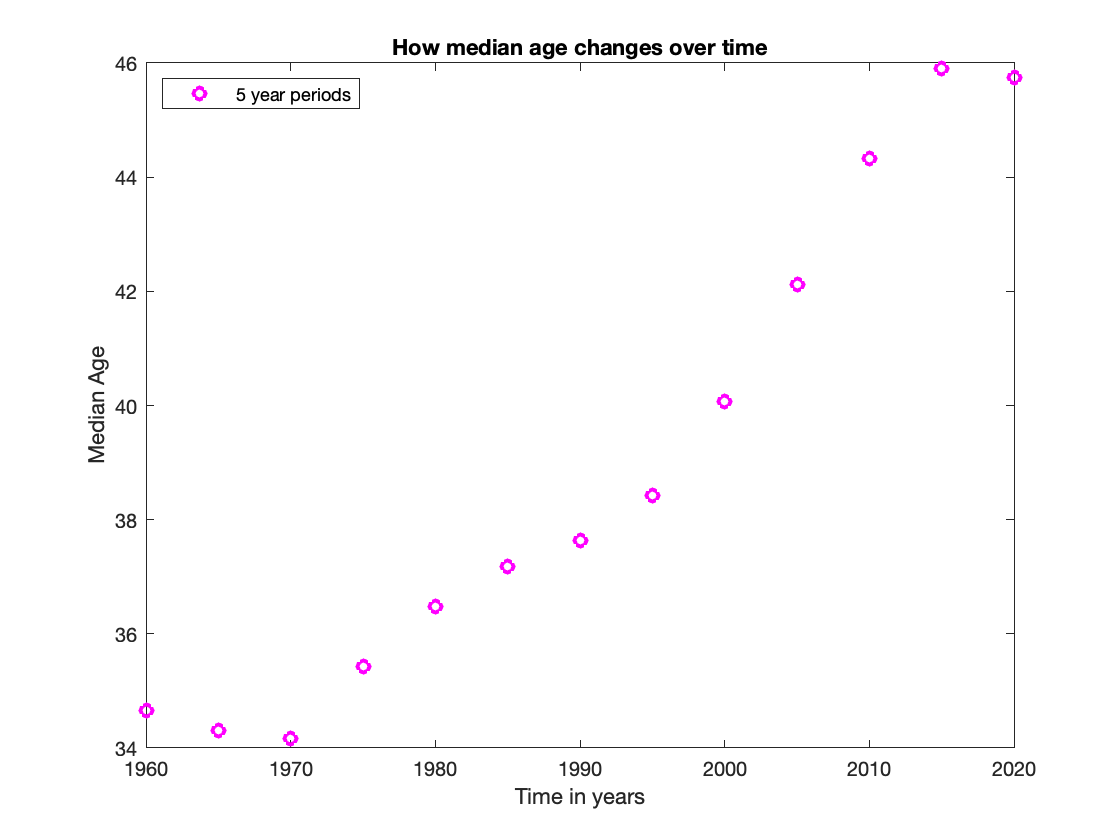

plot(years(1:5:end), median_age(1:5:end), 'mo', 'LineWidth', 2)
hold on

xlabel('Time in years')
ylabel('Median Age')

title('How median age changes over time')
legend('5 year periods', 'Location', 'northwest')
hold off

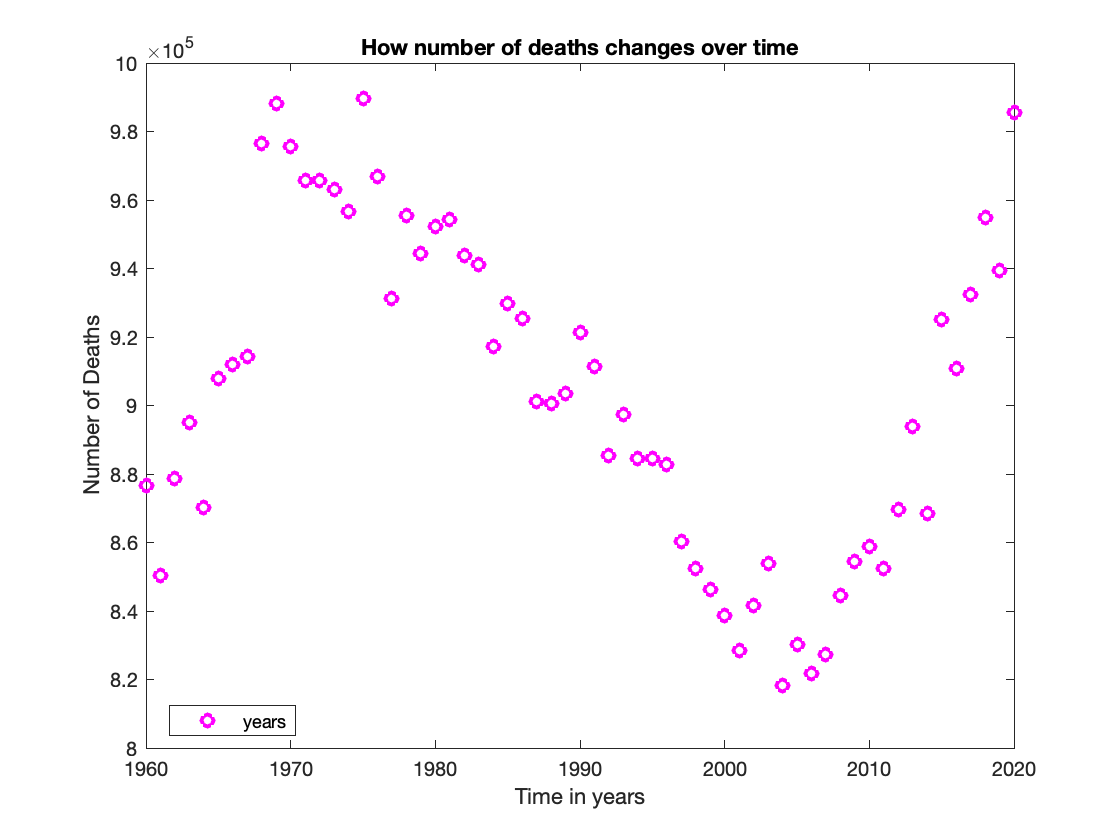


plot(years, total_deaths, 'mo', 'LineWidth', 2)
hold on

xlabel('Time in years')
ylabel('Number of Deaths')

title('How number of deaths changes over time')
legend('years', 'Location', 'best')
hold off

## Analyse correlation between mortality and median age

The correlation between the two variables is studied through a linear model, which unfortunately gives a value for R square very close to zero and therefore suggests that no correlation is observed.

%%% grouping total deaths into 5 year periods

group_number = length(total_deaths) / 5;
grouped_deaths = zeros(12, 1);

for i = 1:group_number
    
    grouped_deaths(i) = mean(total_deaths(i:i + 4));
    % grouped_deaths(i) = sum(total_deaths(i:i + 4));
    
end

%%% linear model

linear_model = fitlm(median_age(1:5:end-1), grouped_deaths);

formula = linear_model.Formula

formula = y ~ 1 + x1

Rsquare = linear_model.Rsquared

Rsquare = struct with fields:
    Ordinary: 0.6905
    Adjusted: 0.6595


The correlation plot of the two variables also confirms that they cannot be related linearly.

plot(median_age(1:5:end - 1), grouped_deaths, 'o')
hold on

f1 = fit(median_age(1:5:end - 1), grouped_deaths, 'm*x+b')

f1 =      General model:
     f1(x) = m*x+b
     Coefficients (with 95% confidence bounds):
       b =   6.241e+05  (4.776e+05, 7.707e+05)
       m =        8054  (4255, 1.185e+04)

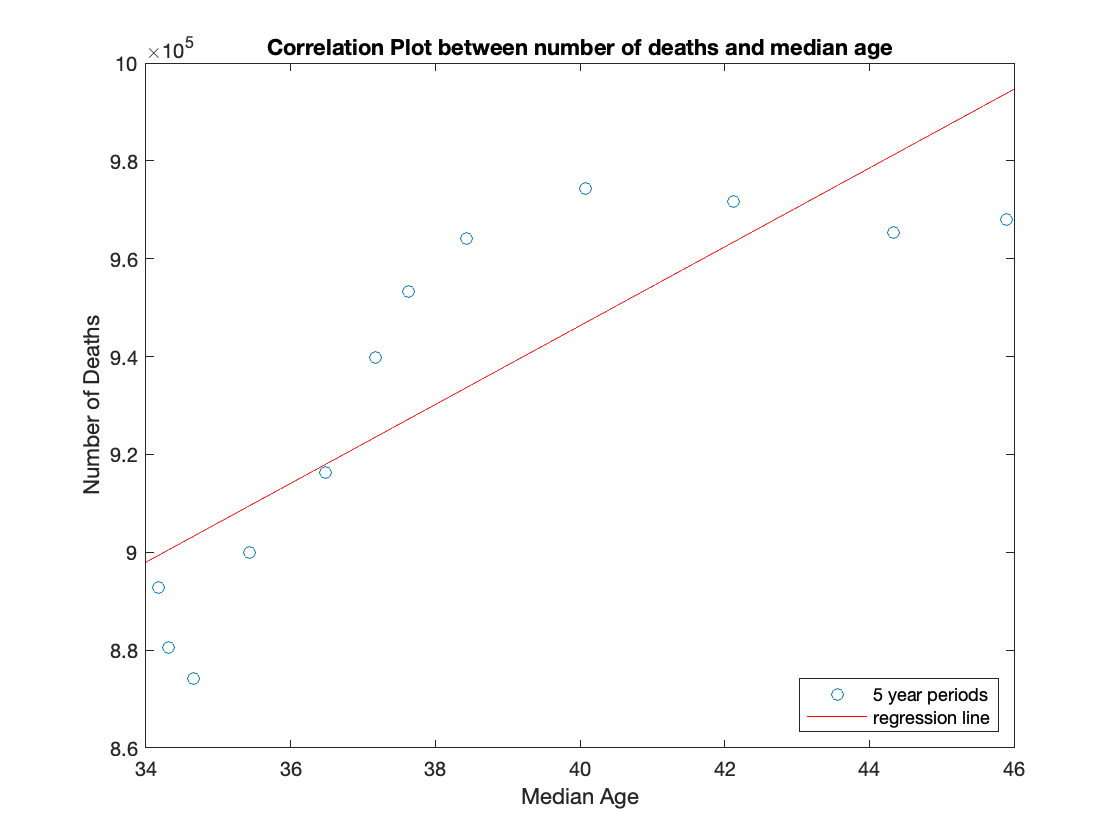

plot(f1, 'r')

title('Correlation Plot between number of deaths and median age')

xlabel('Median Age')
ylabel('Number of Deaths')

legend('5 year periods', 'regression line', 'Location', 'southeast')
hold off


CI = confint(f1);
display(['slope_uncertainty: ', num2str((CI(2,1) - CI(1,1)) / 2)])

slope_uncertainty: 146576.0129


display(['intercept_uncertainty: ', num2str((CI(2,2) - CI(1,2)) / 2)])

intercept_uncertainty: 3799.5198


## Focus on the most recent years

If the focus is drawn onto a shorter timelapse, then a temporary correlation could be identified between the two variables.

It is possible to relate the number of deaths to the median age in a linear fashion for the last two 5 year periods (2010 - 2014 and 2015 - 2019), from which the numbers for the following period (2020 - 2024) could be deduced.

groups_back = 1;
years_back = 5 * groups_back + 5;

tSpan = years(end - years_back:end - 1);
myMedianAge = median_age(end - years_back:5:end - 1);
myGroupedDeaths = grouped_deaths(end - groups_back:end);

plot(myMedianAge, myGroupedDeaths, 'o')
hold on

f2 = fit(myMedianAge, myGroupedDeaths, 'm*x+b')

f2 =      General model:
     f2(x) = m*x+b
     Coefficients:
       b =   8.861e+05
       m =        1787

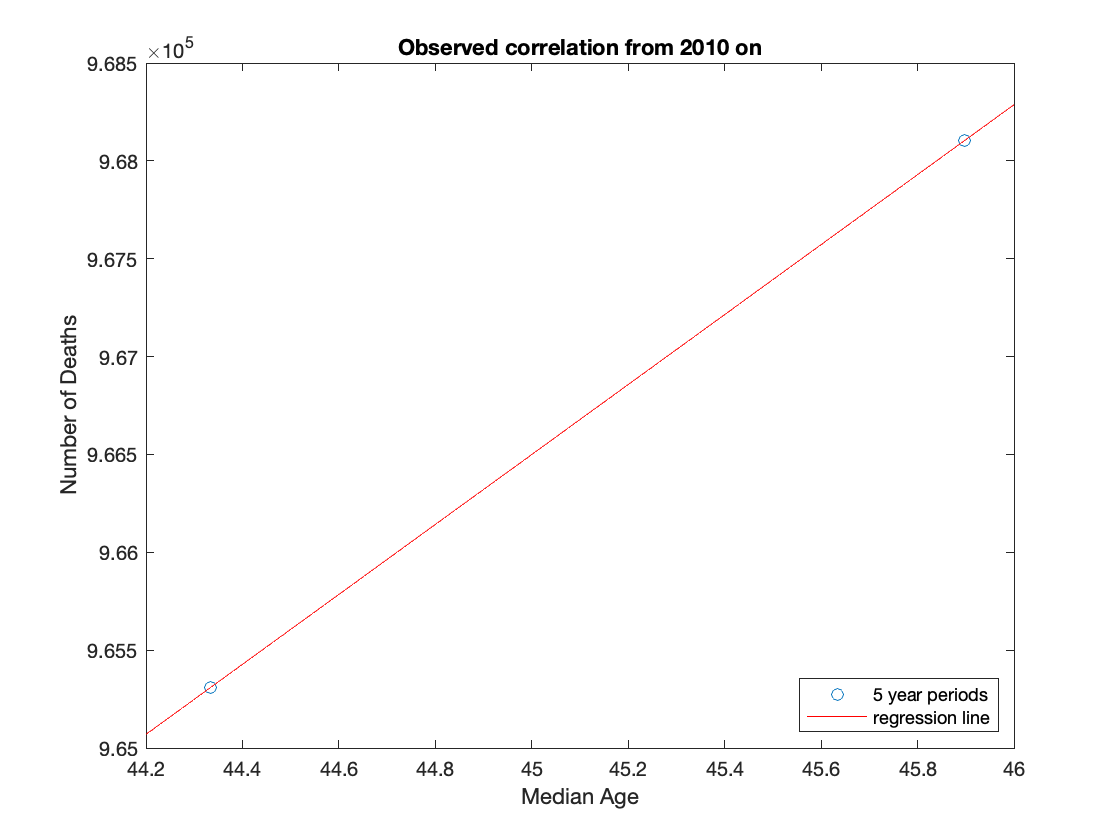

plot(f2, 'r')

title(['Observed correlation from ', num2str(tSpan(1)), ' on'])

xlabel('Median Age')
ylabel('Number of Deaths')

legend('5 year periods', 'regression line', 'Location', 'southeast')
hold off


% CI = confint(f2);
% display(['slope_uncertainty: ', num2str((CI(2,1) - CI(1,1)) / 2)])
% display(['intercept_uncertainty: ', num2str((CI(2,2) - CI(1,2)) / 2)])